cavity_vertical = readtable("cavity/vertical_line_data.csv");

Error using readtable
Unable to find or open 'cavity/vertical_line_data.csv'. Check the path and filename or file permissions.

y_ghia = [0; 0.0547; 0.0625; 0.0703; 0.1016; 0.1719; 0.2813; ...
    0.4531; 0.5000; 0.6172; 0.7344; 0.8516; 0.9531; 0.9609; ...
    0.9688; 0.9766; 1.0000];
u_0_ghia = [0.0000; -0.18109; -0.20196; -0.22220; -0.29730; ...
    -0.38289; -0.27805; -0.10648; -0.06080; 0.05702; 0.18719;...
    0.33304; 0.46604; 0.51117; 0.57492; 0.65928; 1.0000];
idx = [1;8;9;10;14;23;37;59;65;80;95;110;123;124;125;126;129];
ghia = table(idx, y_ghia, u_0_ghia);

plot(cavity_vertical.U_0, cavity_vertical.Points_1)

Unable to resolve the name 'cavity_vertical.U_0'.

hold on
scatter(ghia.u_0_ghia, ghia.y_ghia);
hold off

errors = zeros(1,17);
for i=1:17
    errors(i) = ghia.u_0_ghia(i)-cavity_vertical.U_0(ghia.idx(i)+1);
end

Unable to resolve the name 'cavity_vertical.U_0'.

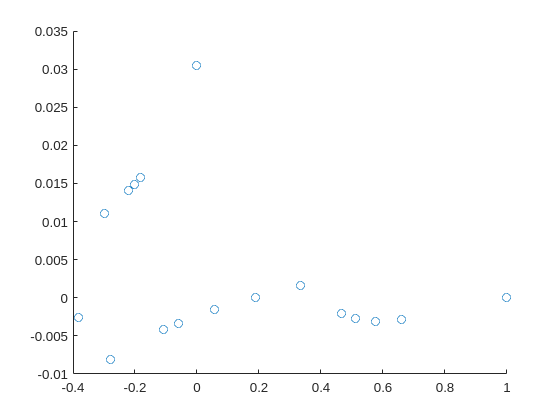

scatter(ghia.u_0_ghia, errors);

poiselle_vertical = readtable("poiselle_exam/vertical_line_data.csv");

poiselle_hor = readtable("poiselle_exam/hor_line_data.csv");

y = linspace(0, 0.5, 51);
u = linspace(0,1,51);
for i = 1:51
u(i) = (2.4/0.05)/2*(y(i)*(0.5-y(i)));
end

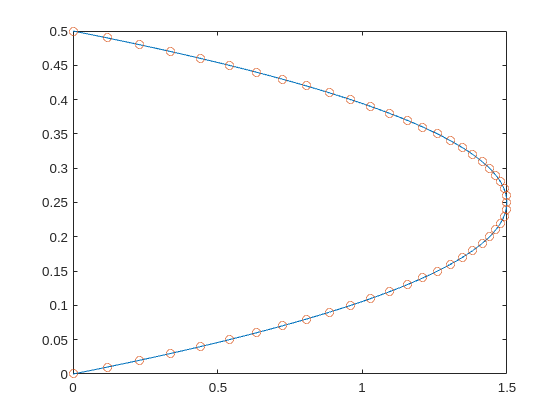

plot(poiselle_vertical.U_0, poiselle_vertical.Points_1)
hold on
scatter(u,y);
hold off

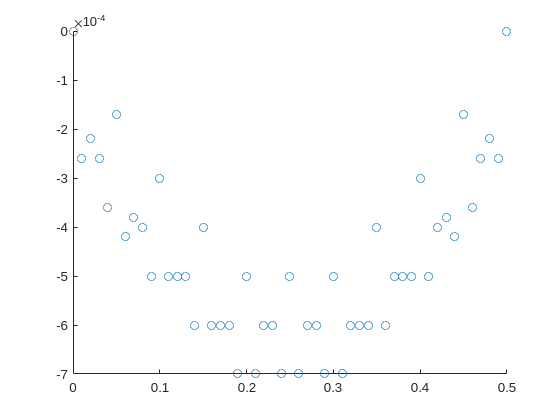

errors = linspace(1,50,51);
errors(1) = u(1)-poiselle_vertical.U_1(1);
for i=2:51
    errors(i) = poiselle_vertical.U_0(2*i-1)-u(i);
end
scatter(y, errors);